## Tuberculosis Data - Pairwise interactions

**Article:** nature.com/articles/s41598-019-48410-y

testFile = 'tb_pairwise.xlsx';
trainingData = 'orig_ecoli.xlsx';
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;

summaryTable = 1×12 table
     min      median      max     range     mean        std      interactionCount    synergyCount    antagonismCount    orthologsCount    rejectNormality    pNormality
    ______    _______    _____    _____    _______    _______    ________________    ____________    _______________    ______________    _______________    __________

    -0.761    0.30585    0.891    1.652    0.29137    0.35096           28                5                23                3190              false          0.058894 


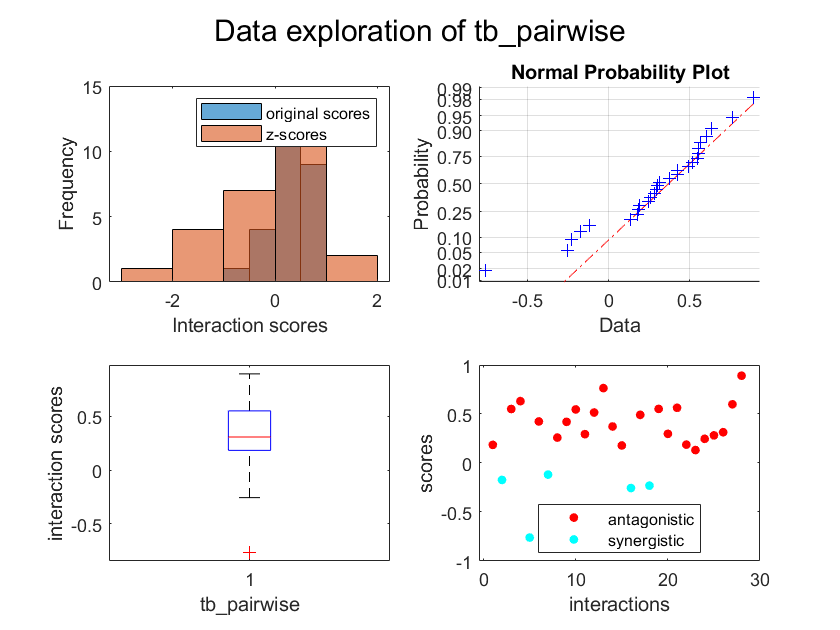

[summary,drugList] = dataExplore(testFile);

compareFiles = {testFile,'orig_ecoli.xlsx'};
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    tb_pairwise score    orig_ecoli score
    ______    ______    _________________    ________________

    "CHL"     "FUS"           -0.173              -0.817     
    "CHL"     "NIT"            0.631              1.2535     
    "CHL"     "RIF"           -0.761               0.244     
    "CHL"     "VAN"          -0.1186               0.081     
    "FUS"     "NIT"           0.1789              1.1785     
    "FUS"     "RIF"          -0.2557              -0.819     
    "FUS"     "VAN"          -0.2311             -1.3925     
    "NIT"     "RIF"           0.1316               3.022     


interactionCounts = 2×2 table
                   tb_pairwise    orig_ecoli
                   ___________    __________

    tb_pairwise         0             10    
    orig_ecoli          0              0    


R_values = 2×2 table
                   tb_pairwise    orig_ecoli
                   ___________    __________

    tb_pairwise         0          0.70909  
    orig_ecoli          0                0  


P_values = 2×2 table
                   tb_pairwise    orig_ecoli
                   ___________    __________

    tb_pairwise         0          0.027514 
    orig_ecoli          0                 0 


orthologCounts = 2×2 table
                   tb_pairwise    orig_ecoli
                   ___________    __________

    tb_pairwise         0             0     
    orig_ecoli          0             0     


indigoSummary = indigoRun(testFile,trainingData,valMethod,K, standardize,input_type);

Run 1
Elapsed time is 25.015563 seconds.
Run 2
Elapsed time is 22.720897 seconds.
Run 3
Elapsed time is 27.491050 seconds.
Run 4
Elapsed time is 22.368936 seconds.
Run 5
Elapsed time is 16.389342 seconds.


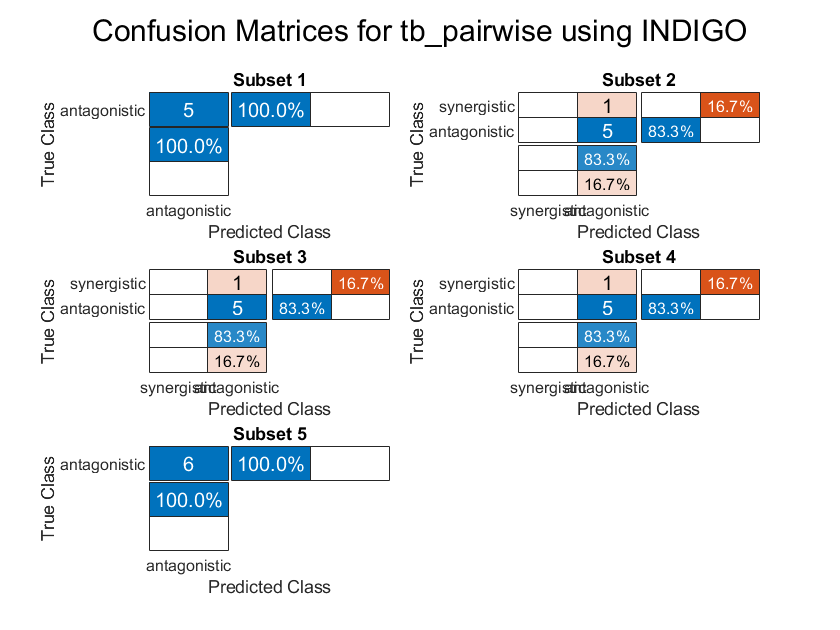

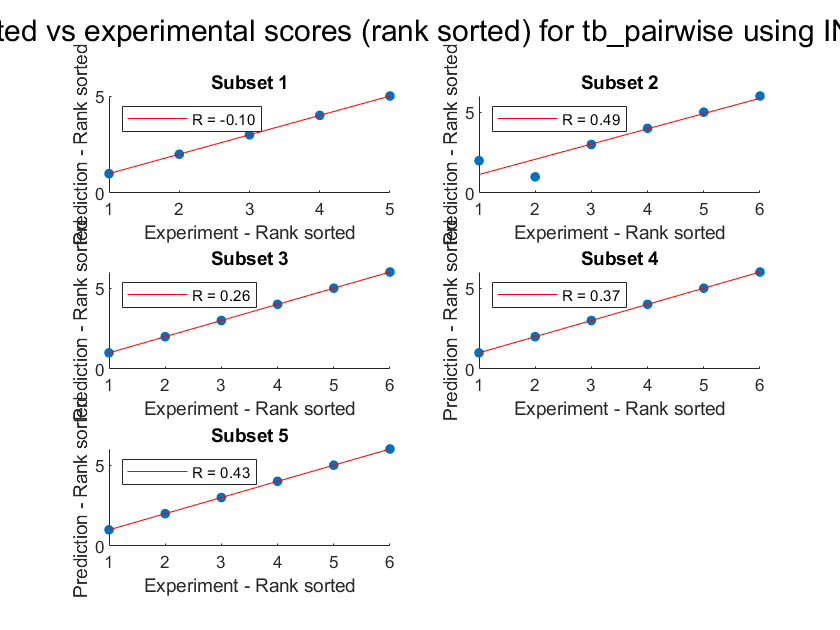

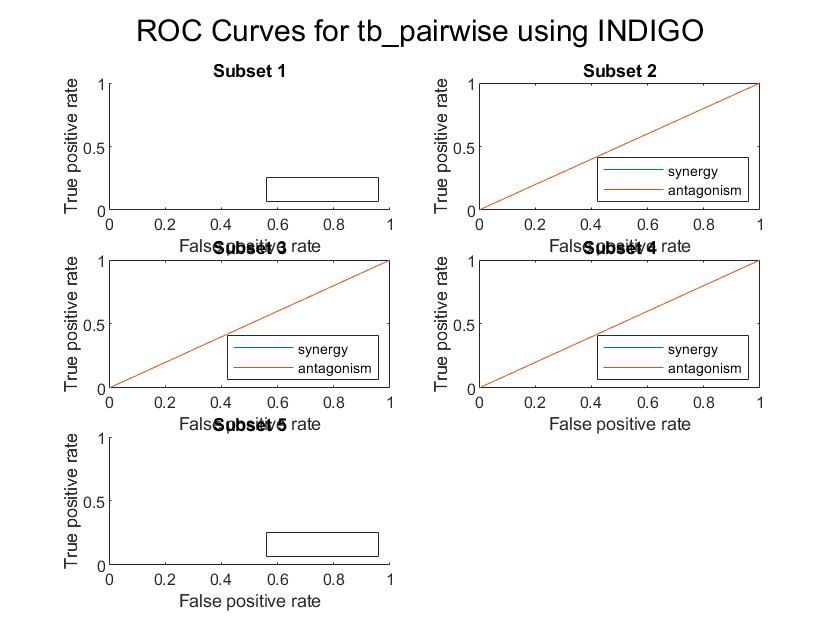

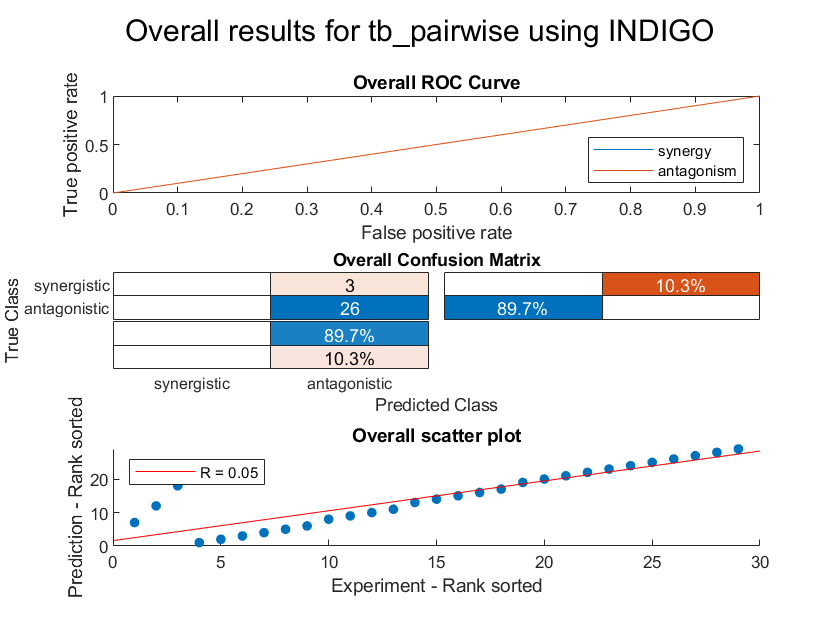

resultsTable = 5×12 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         5             -0.1       

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                    5.8
    R (rank)                    0.28857
    P value                     0.57611
    Accuracy                        0.9
    Absolute error                  0.2
    Precision (synergy)             NaN
    Recall (synergy)                NaN
    Precision (antagonism)          0.9
    Recall (antagonism)               1
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)             NaN
    AUC - ROC (antagonism)          NaN


overviewTable = 12×1 table
                                 Value  
                                ________

    Interactions                      29
    R (rank)                    0.050105
    P value                      0.79632
    Accuracy                     0.89655
    Absolute error                0.2069
    Precision (synergy)              NaN
    Recall (synergy)                   0
    Precision (antagonism)       0.89655
    Recall (antagonism)                1
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)              0.5
    AUC - ROC (antagonism)           0.5


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_pairwise.xlsx';
trainingData = 'orig_ecoli.xlsx';
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K, standardize,input_type);

Run 1
Elapsed time is 26.111459 seconds.
Run 2
Elapsed time is 15.806821 seconds.
Run 3
Elapsed time is 16.016461 seconds.
Run 4
Elapsed time is 21.306494 seconds.
Run 5
Elapsed time is 21.172635 seconds.


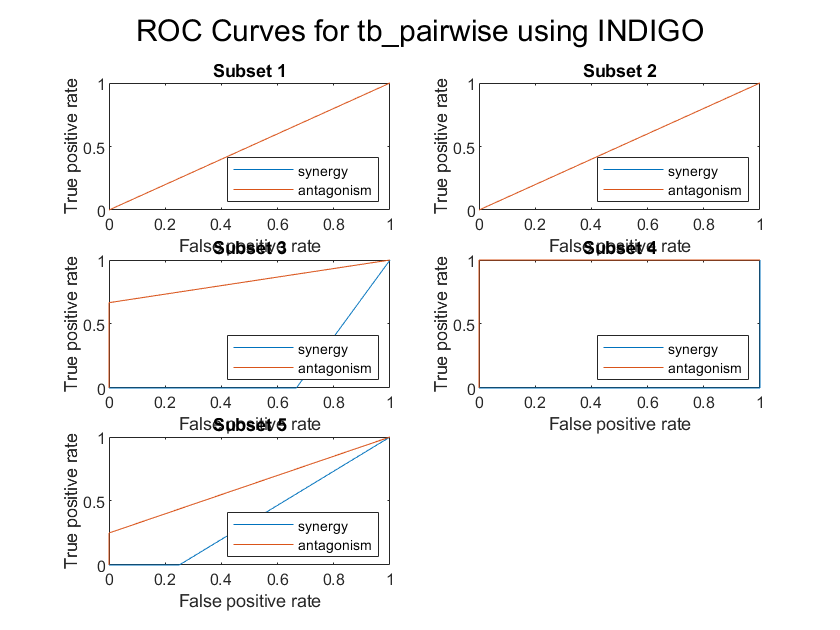

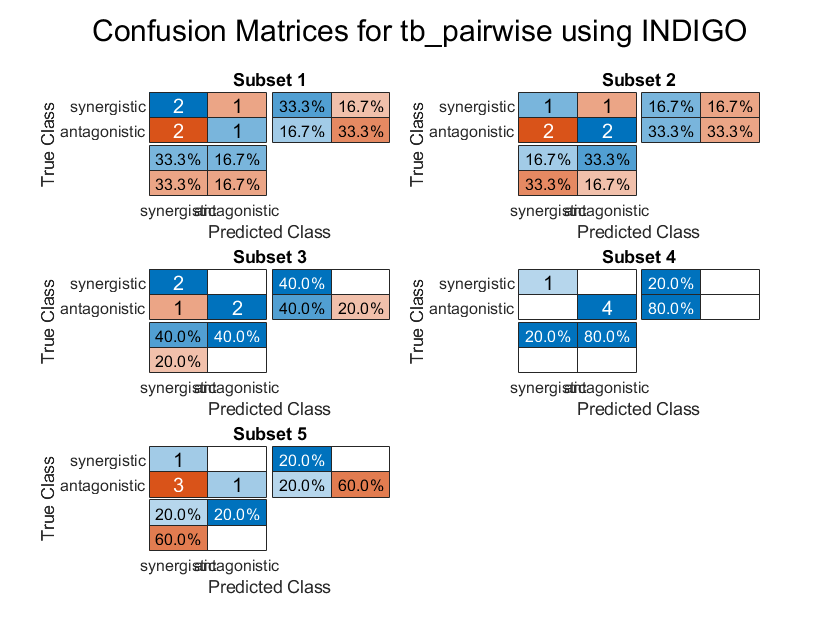

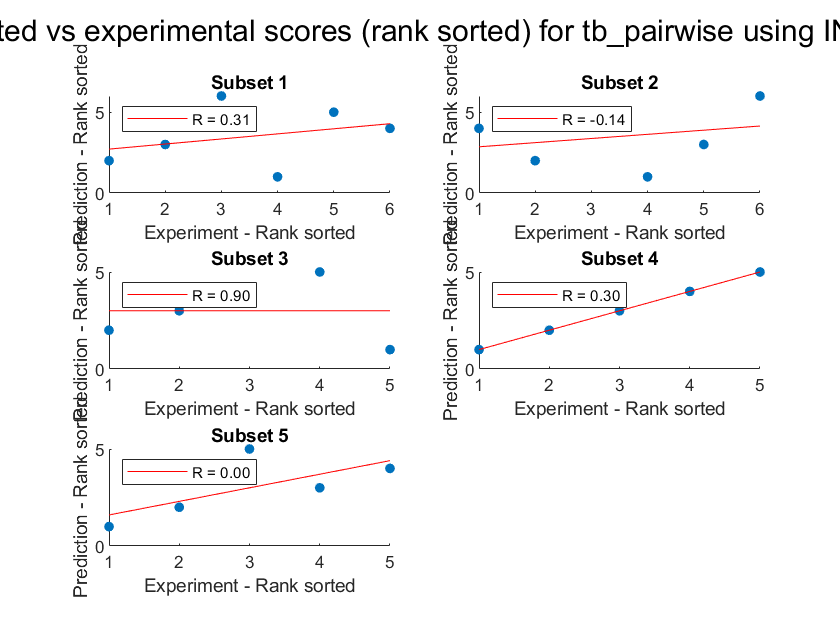

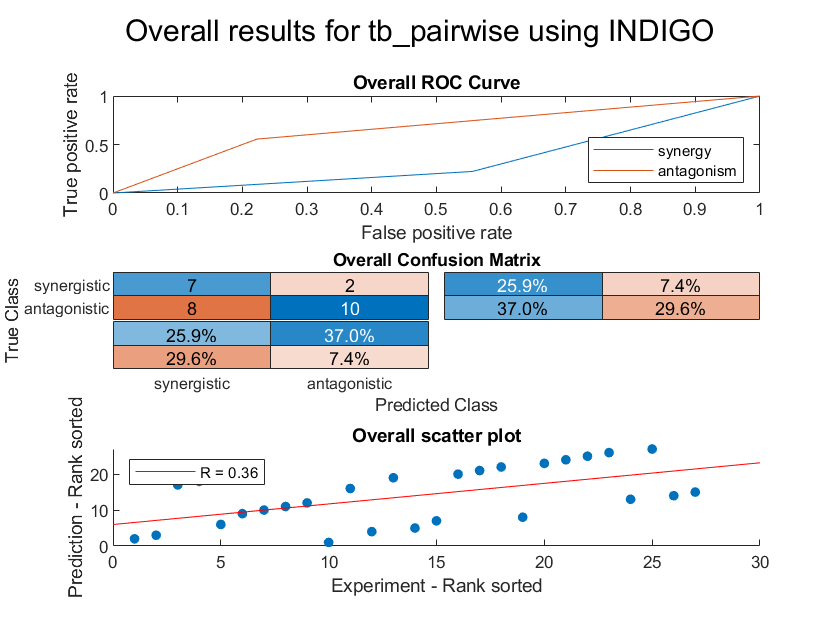

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         6           0.31429    

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                    5.4
    R (rank)                    0.27429
    P value                     0.62667
    Accuracy                       0.64
    Absolute error                 0.72
    Precision (synergy)            0.55
    Recall (synergy)            0.83333
    Precision (antagonism)      0.83333
    Recall (antagonism)            0.55
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.30833
    AUC - ROC (antagonism)      0.69167


overviewTable = 12×1 table
                                 Value  
                                ________

    Interactions                      27
    R (rank)                     0.35802
    P value                     0.066712
    Accuracy                     0.62963
    Absolute error               0.74074
    Precision (synergy)          0.46667
    Recall (synergy)             0.77778
    Precision (antagonism)       0.83333
    Recall (antagonism)          0.55556
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.33333
    AUC - ROC (antagonism)       0.66667


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_pairwise.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'
                'stlt2.xlsx'
                'st14028.xlsx'
                'pao1.xlsx'
                'pa14.xlsx'};
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;

compareFiles = [testFile;trainingData];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 4×4 table
    Drug 1    Drug 2    tb_pairwise score    ecoli_bw25113 score
    ______    ______    _________________    ___________________

    "CHL"     "FUS"          -0.173               -0.16024      
    "CHL"     "NIT"           0.631               0.062737      
    "CHL"     "RIF"          -0.761               -0.35201      
    "FUS"     "NIT"          0.1789                0.10853      


sharedInteractionsPreview = 4×4 table
    Drug 1    Drug 2    tb_pairwise score    ecoli_iAi1 score
    ______    ______    _________________    ________________

    "CHL"     "FUS"          -0.173              -0.32704    
    "CHL"     "NIT"           0.631              -0.41592    
    "CHL"     "RIF"          -0.761                0.1113    
    "FUS"     "NIT"          0.1789              -0.16241    


tb_pairwise and stlt2 have no shared interactions

tb_pairwise and st14028 have no shared interactions



sharedInteractionsPreview = 2×4 table
    Drug 1    Drug 2    tb_pairwise score    pao1 score
    ______    ______    _________________    __________

    "CHL"     "NIT"           0.631            0.08089 
    "NIT"     "RIF"          0.1316           -0.13448 


sharedInteractionsPreview = 2×4 table
    Drug 1    Drug 2    tb_pairwise score    pa14 score
    ______    ______    _________________    __________

    "CHL"     "NIT"           0.631            0.11999 
    "NIT"     "RIF"          0.1316          -0.030558 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    ecoli_iAi1 score
    ______    ______    ___________________    ________________

    "A22"     "ATM"          -0.11682              -0.23949    
    "A22"     "BLM"          -0.18842              -0.22326    
    "A22"     "MMC"          -0.15416              0.081189    
    "A22"     "PUR"           0.10034               0.10767    
    "A22"     "PYO"           0.28322             -0.082868    
    "A22"     "RIF"          0.099699               0.17919    
    "AMK"     "AZM"           0.20244              0.039346    
    "AMK"     "BZK"           0.40112              0.082268    


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    stlt2 score
    ______    ______    ___________________    ___________

    "A22"     "MMC"           -0.15416           0.19836  
    "AMK"     "BZK"            0.40112           0.29453  
    "AMK"     "EGCG"           0.13458           0.13635  
    "AMK"     "ERI"            0.20099           0.15979  
    "AMK"     "LCX"          -0.044191          -0.36433  
    "AMK"     "PMS"            0.48777           0.31997  
    "AMK"     "PRC"            0.47286           0.19732  
    "AMK"     "PUR"           -0.42117          -0.28867  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    st14028 score
    ______    ______    ___________________    _____________

    "A22"     "MMC"           -0.15416            0.046942  
    "AMK"     "BZK"            0.40112             0.28743  
    "AMK"     "EGCG"           0.13458            0.023459  
    "AMK"     "ERI"            0.20099           -0.035934  
    "AMK"     "LCX"          -0.044191            -0.42079  
    "AMK"     "PMS"            0.48777            -0.11198  
    "AMK"     "PRC"            0.47286            0.076645  
    "AMK"     "PUR"           -0.42117           -0.099679  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    pao1 score
    ______    ______    ___________________    __________

    "A22"     "ATM"          -0.11682           0.040284 
    "A22"     "MMC"          -0.15416          -0.099203 
    "AMK"     "AZM"           0.20244            0.68877 
    "AMK"     "EGCG"          0.13458            0.14272 
    "AMK"     "ERI"           0.20099            0.28607 
    "AMK"     "MMC"           -0.2502           0.062727 
    "AMK"     "NIT"          -0.21472            0.22065 
    "AMK"     "PRC"           0.47286            0.19014 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    pa14 score
    ______    ______    ___________________    __________

    "A22"     "ATM"          -0.11682           -0.11745 
    "A22"     "MMC"          -0.15416            0.27324 
    "AMK"     "AZM"           0.20244            0.40503 
    "AMK"     "EGCG"          0.13458           0.083746 
    "AMK"     "ERI"           0.20099            0.20578 
    "AMK"     "MMC"           -0.2502            0.12617 
    "AMK"     "NIT"          -0.21472          -0.052538 
    "AMK"     "PRC"           0.47286             0.1142 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    stlt2 score
    ______    ______    ________________    ___________

    "A22"     "MMC"         0.081189          0.19836  
    "AMK"     "BZK"         0.082268          0.29453  
    "AMK"     "EGCG"        0.034852          0.13635  
    "AMK"     "ERI"         0.047723          0.15979  
    "AMK"     "LCX"          -0.1704         -0.36433  
    "AMK"     "PMS"         0.048965          0.31997  
    "AMK"     "PRC"         0.059603          0.19732  
    "AMK"     "PUR"         -0.26455         -0.28867  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    st14028 score
    ______    ______    ________________    _____________

    "A22"     "MMC"         0.081189           0.046942  
    "AMK"     "BZK"         0.082268            0.28743  
    "AMK"     "EGCG"        0.034852           0.023459  
    "AMK"     "ERI"         0.047723          -0.035934  
    "AMK"     "LCX"          -0.1704           -0.42079  
    "AMK"     "PMS"         0.048965           -0.11198  
    "AMK"     "PRC"         0.059603           0.076645  
    "AMK"     "PUR"         -0.26455          -0.099679  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    pao1 score
    ______    ______    ________________    __________

    "A22"     "ATM"         -0.23949         0.040284 
    "A22"     "MMC"         0.081189        -0.099203 
    "AMK"     "AZM"         0.039346          0.68877 
    "AMK"     "EGCG"        0.034852          0.14272 
    "AMK"     "ERI"         0.047723          0.28607 
    "AMK"     "MMC"         -0.11537         0.062727 
    "AMK"     "NIT"         -0.30784          0.22065 
    "AMK"     "PRC"         0.059603          0.19014 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    pa14 score
    ______    ______    ________________    __________

    "A22"     "ATM"         -0.23949         -0.11745 
    "A22"     "MMC"         0.081189          0.27324 
    "AMK"     "AZM"         0.039346          0.40503 
    "AMK"     "EGCG"        0.034852         0.083746 
    "AMK"     "ERI"         0.047723          0.20578 
    "AMK"     "MMC"         -0.11537          0.12617 
    "AMK"     "NIT"         -0.30784        -0.052538 
    "AMK"     "PRC"         0.059603           0.1142 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    st14028 score
    ______    ______    ___________    _____________

    "A22"     "GEN"       0.12582          0.16781  
    "A22"     "MMC"       0.19836         0.046942  
    "AMK"     "ATM"      -0.30991         -0.14214  
    "AMK"     "BZK"       0.29453          0.28743  
    "AMK"     "CEC"      -0.11493         -0.16492  
    "AMK"     "EGCG"      0.13635         0.023459  
    "AMK"     "ERI"       0.15979        -0.035934  
    "AMK"     "LCX"      -0.36433         -0.42079  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    pao1 score
    ______    ______    ___________    __________

    "A22"     "MMC"        0.19836     -0.099203 
    "AMK"     "ATM"       -0.30991      -0.32109 
    "AMK"     "EGCG"       0.13635       0.14272 
    "AMK"     "ERI"        0.15979       0.28607 
    "AMK"     "PRC"        0.19732       0.19014 
    "AMK"     "TOB"       -0.33487      -0.13132 
    "AMX"     "AMK"        -0.1155      -0.19518 
    "AMX"     "CIP"      -0.047861      0.097174 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    pa14 score
    ______    ______    ___________    __________

    "A22"     "MMC"        0.19836       0.27324 
    "AMK"     "ATM"       -0.30991      -0.50344 
    "AMK"     "EGCG"       0.13635      0.083746 
    "AMK"     "ERI"        0.15979       0.20578 
    "AMK"     "PRC"        0.19732        0.1142 
    "AMK"     "TOB"       -0.33487      -0.12544 
    "AMX"     "AMK"        -0.1155       -0.2228 
    "AMX"     "CIP"      -0.047861        0.2668 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    st14028 score    pao1 score
    ______    ______    _____________    __________

    "A22"     "MMC"        0.046942      -0.099203 
    "AMK"     "ATM"        -0.14214       -0.32109 
    "AMK"     "EGCG"       0.023459        0.14272 
    "AMK"     "ERI"       -0.035934        0.28607 
    "AMK"     "PRC"        0.076645        0.19014 
    "AMK"     "TOB"        -0.10058       -0.13132 
    "AMX"     "AMK"          -0.145       -0.19518 
    "AMX"     "CIP"         0.22995       0.097174 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    st14028 score    pa14 score
    ______    ______    _____________    __________

    "A22"     "MMC"        0.046942        0.27324 
    "AMK"     "ATM"        -0.14214       -0.50344 
    "AMK"     "EGCG"       0.023459       0.083746 
    "AMK"     "ERI"       -0.035934        0.20578 
    "AMK"     "PRC"        0.076645         0.1142 
    "AMK"     "TOB"        -0.10058       -0.12544 
    "AMX"     "AMK"          -0.145        -0.2228 
    "AMX"     "CIP"         0.22995         0.2668 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    pao1 score    pa14 score
    ______    ______    __________    __________

    "AMK"     "A22"      0.030386      -0.15949 
    "AMX"     "A22"      0.047543      -0.13341 
    "CHL"     "A22"      0.046395       0.10396 
    "DOX"     "A22"      -0.03145        0.1363 
    "FOF"     "A22"      0.049735      -0.59174 
    "NIT"     "A22"      0.033376       0.14544 
    "PRC"     "A22"      0.042237       0.20696 
    "AMX"     "AMK"      -0.19518       -0.2228 


interactionCounts = 7×7 table
                     tb_pairwise    ecoli_bw25113    ecoli_iAi1    stlt2    st14028    pao1    pa14
                     ___________    _____________    __________    _____    _______    ____    ____

    tb_pairwise           0               4               4           0         0        2       2 
    ecoli_bw25113         0               0             316         148       148       72      72 
    ecoli_iAi1            0               0               0         148       148       72      72 
    stlt2                 0               0               0           0       248       53      53 
    st14028               0               0   

R_values = 7×7 table
                     tb_pairwise    ecoli_bw25113    ecoli_iAi1    stlt2     st14028      pao1       pa14  
                     ___________    _____________    __________    ______    _______    ________    _______

    tb_pairwise           0              0.8             -0.8           0          0           1          1
    ecoli_bw25113         0                0          0.64896       0.745    0.67384     0.24449    0.39303
    ecoli_iAi1            0                0                0      0.6407    0.64464    0.081516     0.3926
    stlt2                 0                0                0           0    0.61859     0.56628    0.52959
    st14028     

P_values = 7×7 table
                     tb_pairwise    ecoli_bw25113    ecoli_iAi1    stlt2    st14028       pao1          pa14   
                     ___________    _____________    __________    _____    _______    __________    __________

    tb_pairwise           0            0.33333        0.33333        0         0                1             1
    ecoli_bw25113         0                  0              0        0         0         0.038725    0.00063738
    ecoli_iAi1            0                  0              0        0         0           0.4952    0.00064705
    stlt2                 0                  0              0        0         0       1.4236e-05     5.914e-05


orthologCounts = 7×7 table
                     tb_pairwise    ecoli_bw25113    ecoli_iAi1    stlt2    st14028    pao1    pa14
                     ___________    _____________    __________    _____    _______    ____    ____

    tb_pairwise           0               0             2838       2326      2337      1292    1299
    ecoli_bw25113         0               0                0          0         0         0       0
    ecoli_iAi1            0               0                0       3107      3107      2026    2026
    stlt2                 0               0                0          0      3220      1879    1876
    st14028               0               0      

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 248.675444 seconds.
Run 2
Elapsed time is 187.931301 seconds.
Run 3
Elapsed time is 175.300932 seconds.
Run 4
Elapsed time is 163.926979 seconds.
Run 5
Elapsed time is 169.069999 seconds.


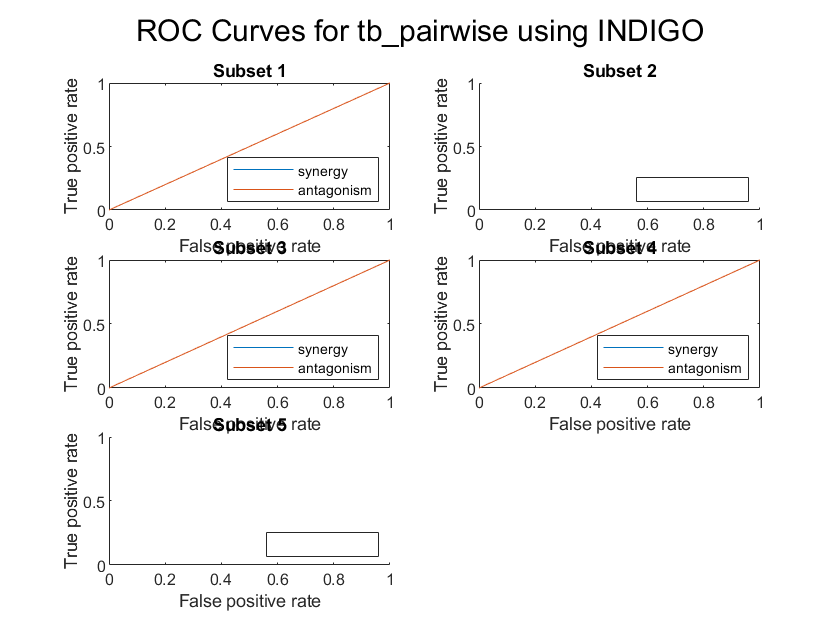

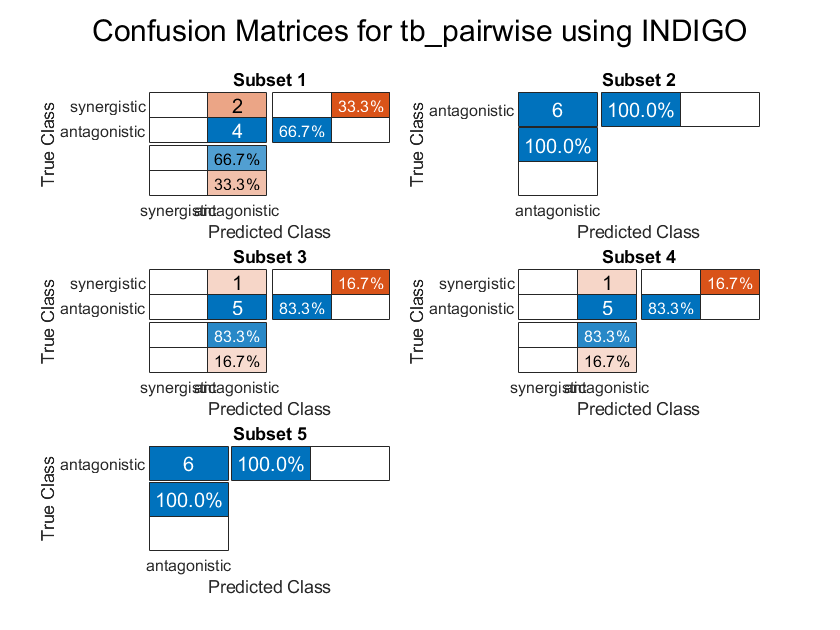

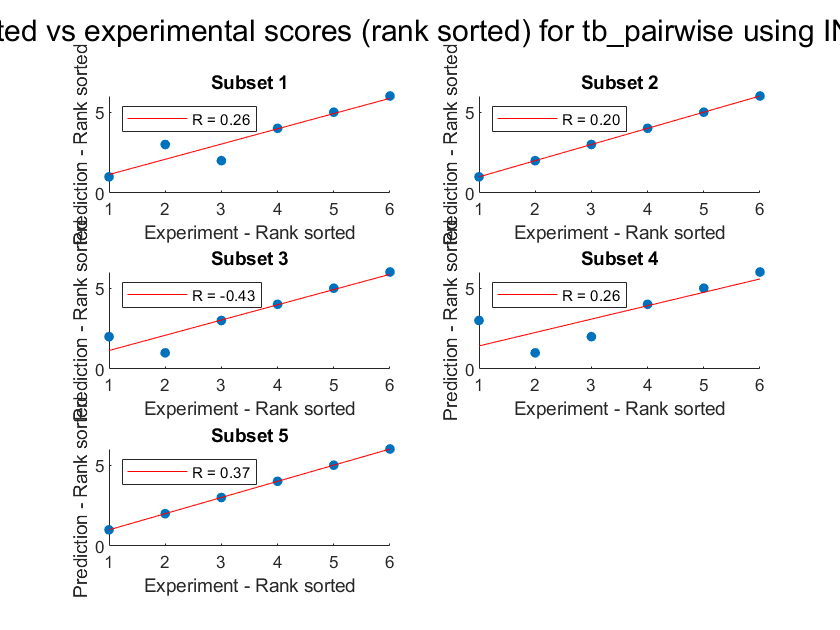

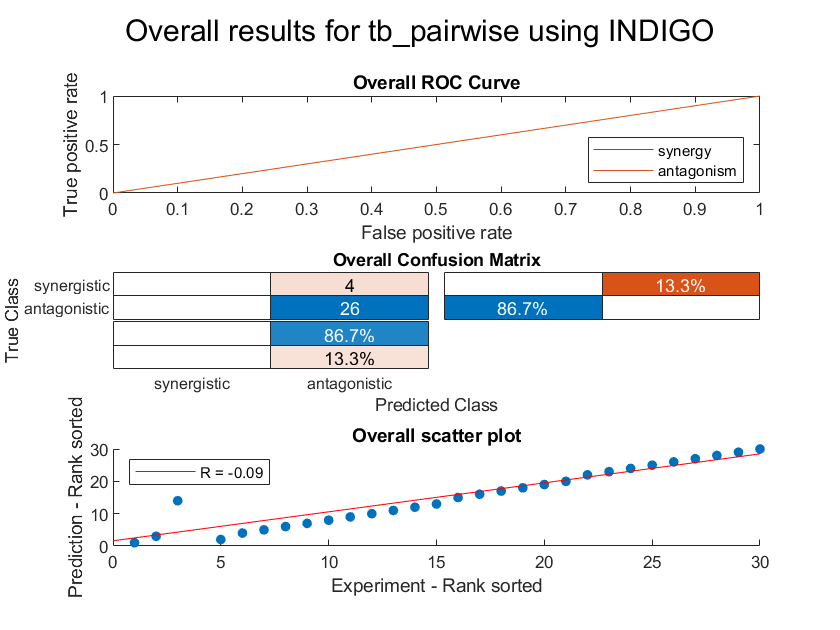

resultsTable = 5×12 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         6           0.25714    0.

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      6
    R (rank)                    0.13143
    P value                     0.58944
    Accuracy                    0.86667
    Absolute error              0.26667
    Precision (synergy)             NaN
    Recall (synergy)                NaN
    Precision (antagonism)      0.86667
    Recall (antagonism)               1
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)             NaN
    AUC - ROC (antagonism)          NaN


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       30
    R (rank)                    -0.094941
    P value                       0.61775
    Accuracy                      0.86667
    Absolute error                0.26667
    Precision (synergy)               NaN
    Recall (synergy)                    0
    Precision (antagonism)        0.86667
    Recall (antagonism)                 1
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)               0.5
    AUC - ROC (antagonism)            0.5


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'tb_pairwise.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'
                'stlt2.xlsx'
                'st14028.xlsx'
                'pao1.xlsx'
                'pa14.xlsx'};
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 228.329419 seconds.
Run 2
Elapsed time is 182.329135 seconds.
Run 3
Elapsed time is 198.412576 seconds.
Run 4
Elapsed time is 164.050420 seconds.
Run 5
Elapsed time is 147.236520 seconds.


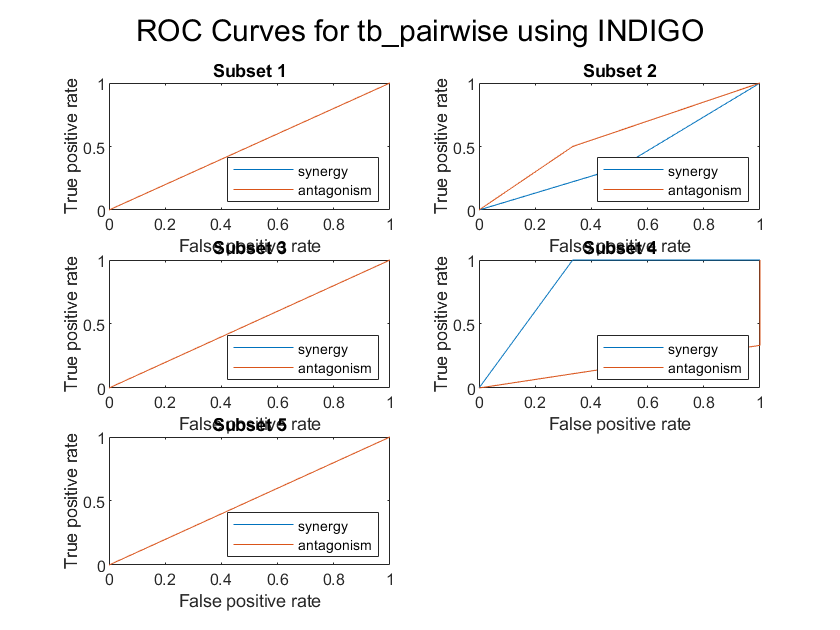

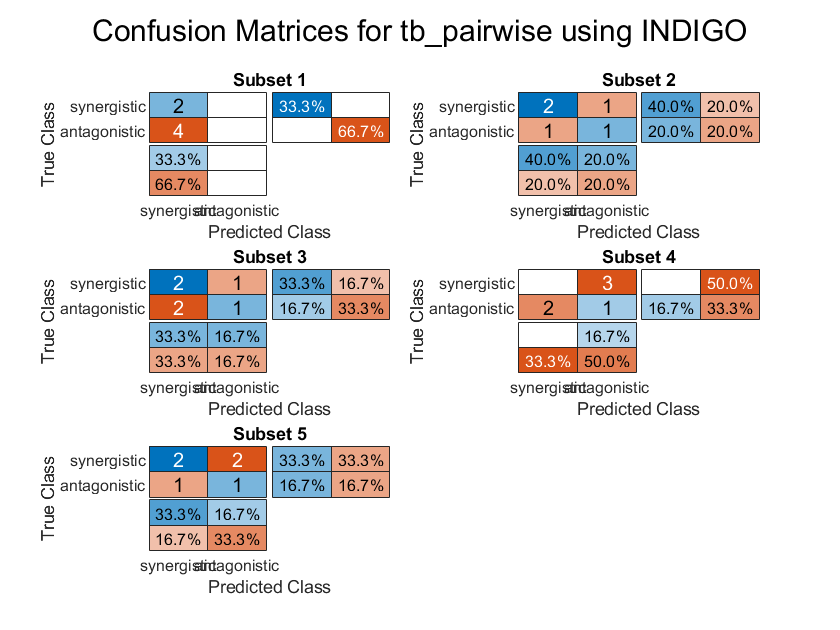

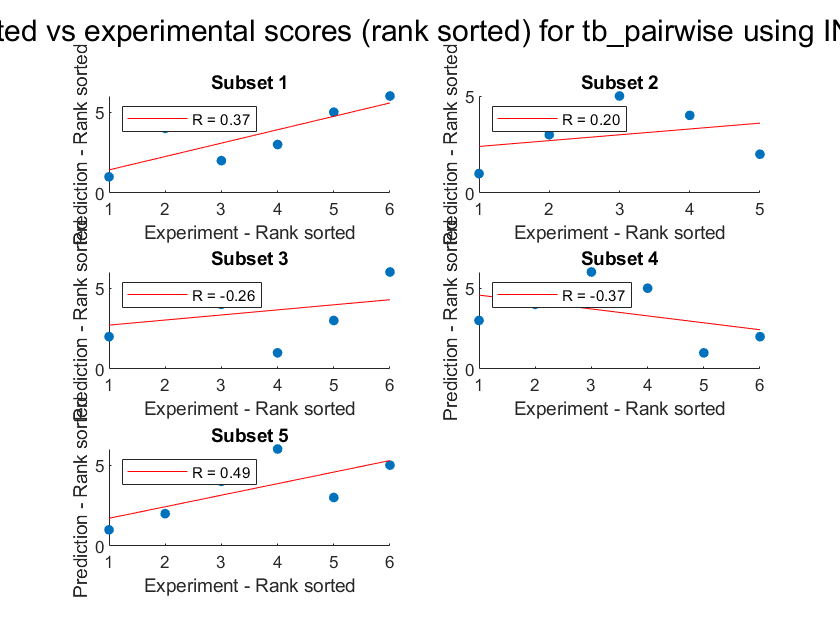

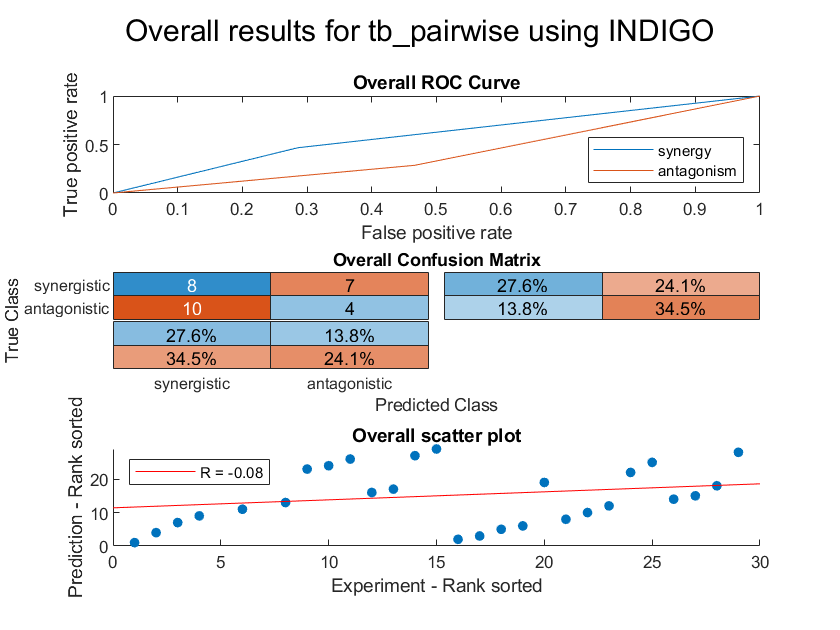

resultsTable = 5×12 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         6           0.37143    0.

averagesTable = 12×1 table
                                 Value  
                                ________

    Interactions                     5.8
    R (rank)                    0.085714
    P value                      0.55833
    Accuracy                        0.42
    Absolute error                  1.16
    Precision (synergy)          0.43333
    Recall (synergy)             0.56667
    Precision (antagonism)           NaN
    Recall (antagonism)          0.33333
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)             0.55
    AUC - ROC (antagonism)          0.45


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       29
    R (rank)                    -0.080484
    P value                       0.67812
    Accuracy                      0.41379
    Absolute error                 1.1724
    Precision (synergy)           0.44444
    Recall (synergy)              0.53333
    Precision (antagonism)        0.36364
    Recall (antagonism)           0.28571
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.59048
    AUC - ROC (antagonism)        0.40952


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_pairwise.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'};
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 75.466850 seconds.
Run 2
Elapsed time is 75.504323 seconds.
Run 3
Elapsed time is 103.530337 seconds.
Run 4
Elapsed time is 61.956248 seconds.
Run 5
Elapsed time is 64.439495 seconds.


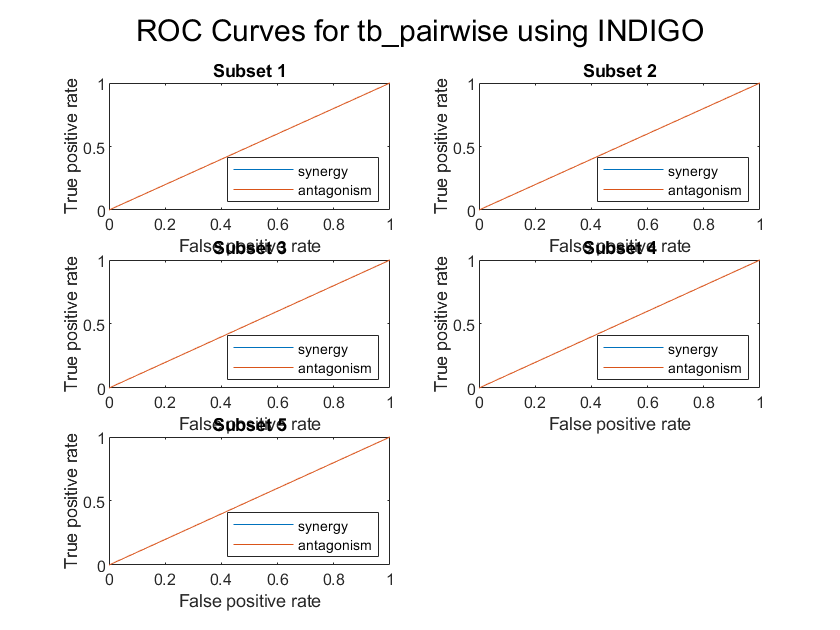

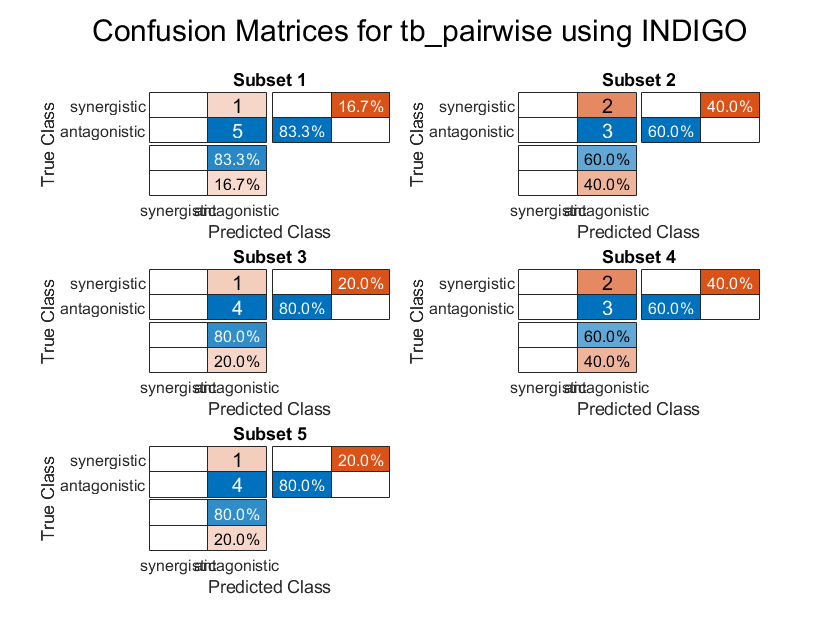

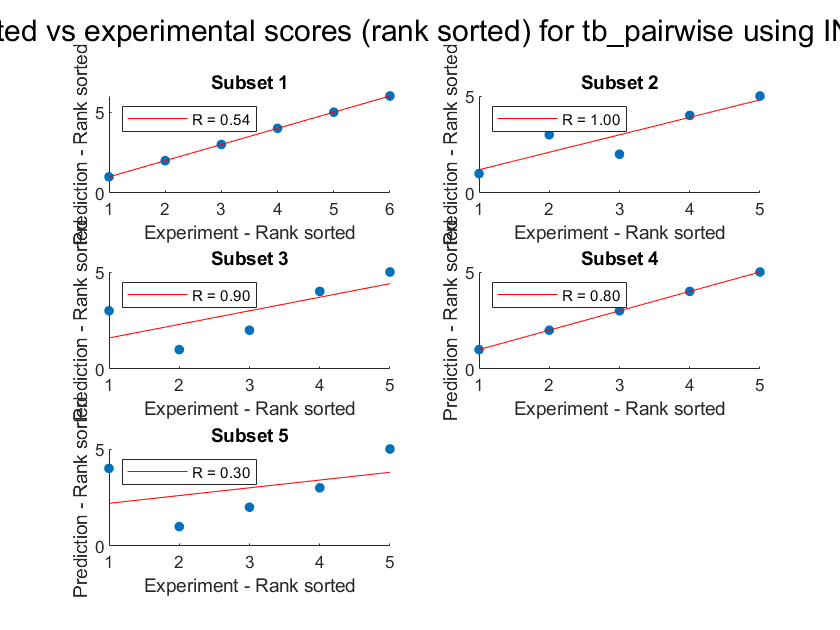

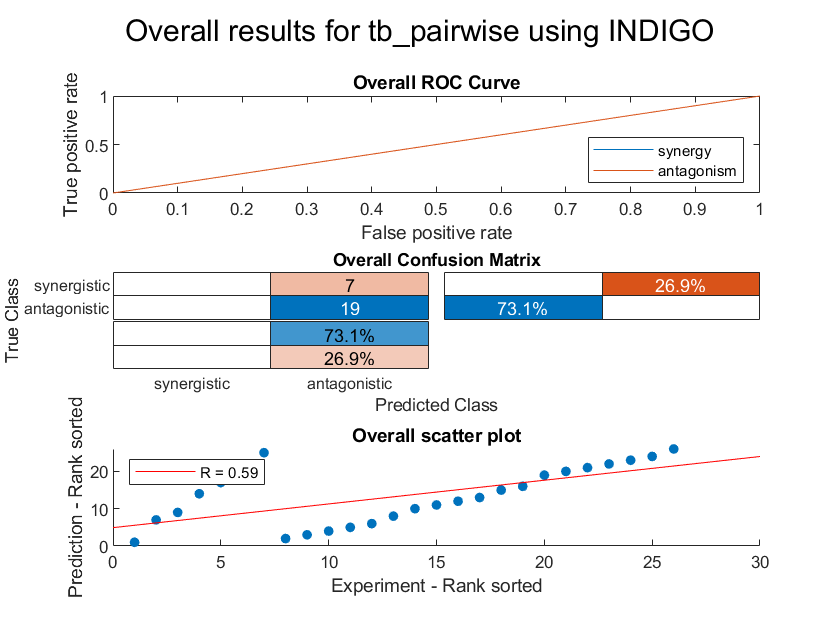

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         6          0.54286     

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                    5.2
    R (rank)                    0.70857
    P value                     0.24278
    Accuracy                    0.72667
    Absolute error              0.54667
    Precision (synergy)             NaN
    Recall (synergy)                  0
    Precision (antagonism)      0.72667
    Recall (antagonism)               1
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)             0.5
    AUC - ROC (antagonism)          0.5


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       26
    R (rank)                      0.58884
    P value                     0.0015524
    Accuracy                      0.73077
    Absolute error                0.53846
    Precision (synergy)               NaN
    Recall (synergy)                    0
    Precision (antagonism)        0.73077
    Recall (antagonism)                 1
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)               0.5
    AUC - ROC (antagonism)            0.5


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_pairwise.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'};
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 71.731617 seconds.
Run 2
Elapsed time is 73.493095 seconds.
Run 3
Elapsed time is 103.020224 seconds.
Run 4
Elapsed time is 105.090277 seconds.
Run 5
Elapsed time is 79.231226 seconds.


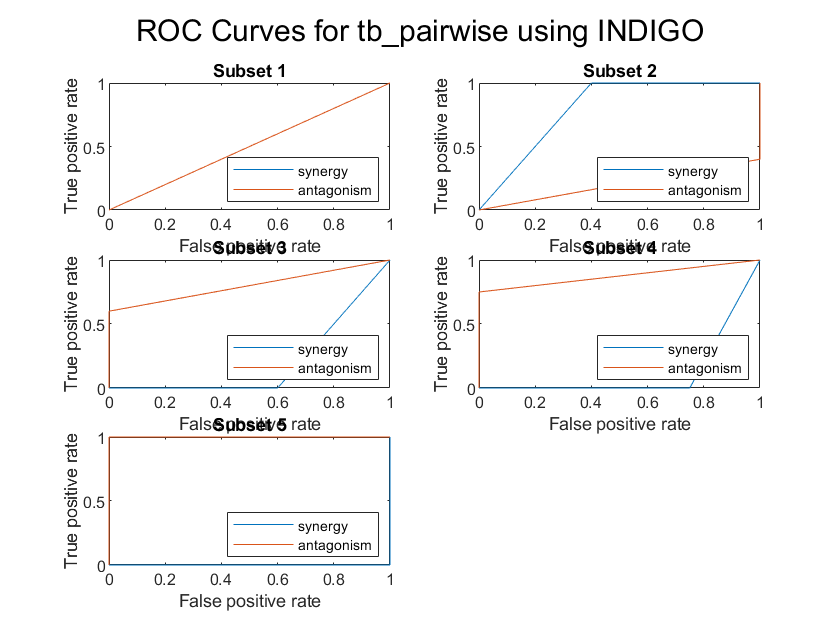

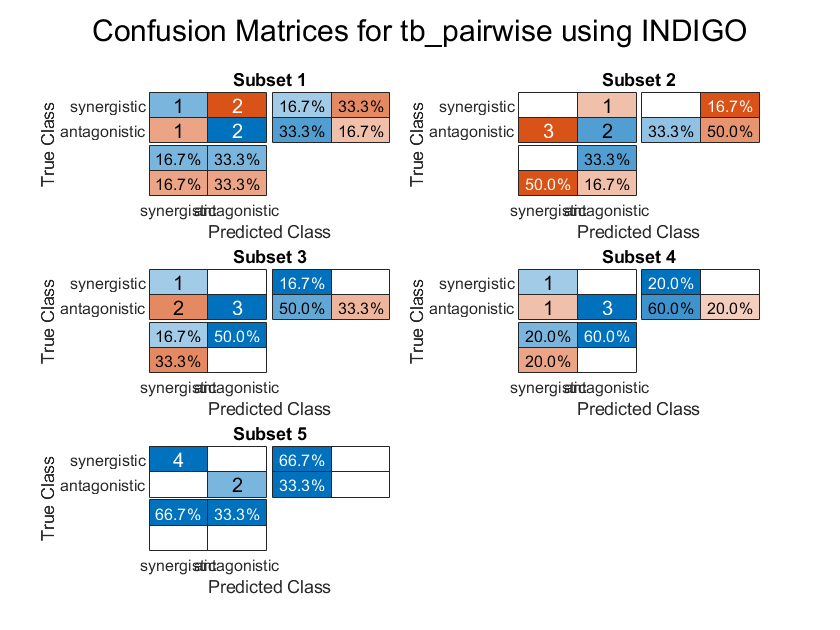

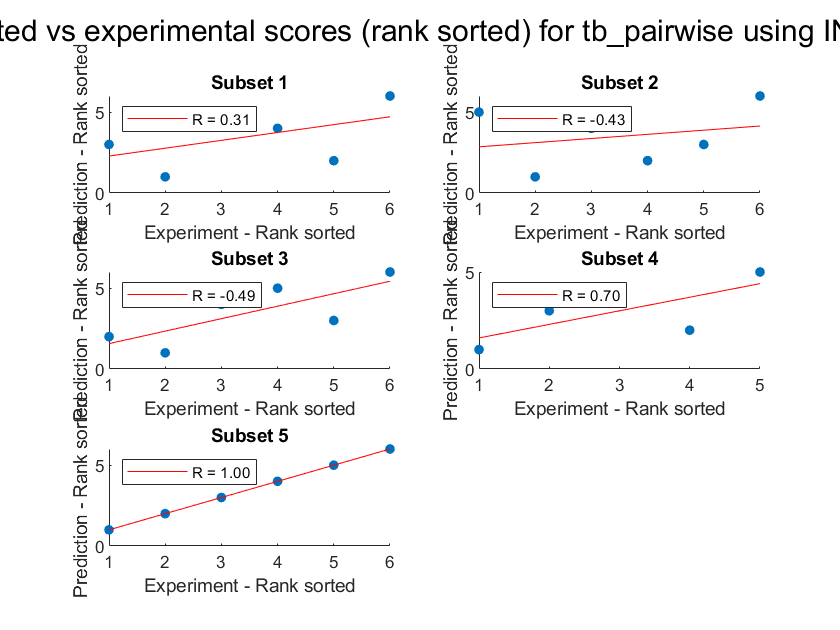

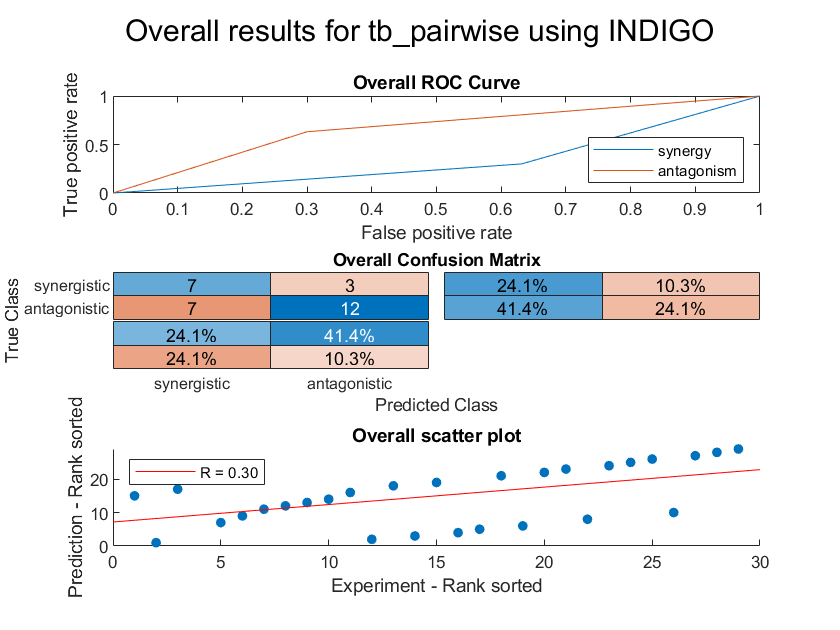

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         6           0.31429  

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                    5.8
    R (rank)                       0.22
    P value                       0.315
    Accuracy                       0.66
    Absolute error                 0.68
    Precision (synergy)         0.46667
    Recall (synergy)            0.66667
    Precision (antagonism)      0.83333
    Recall (antagonism)         0.68333
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)           0.325
    AUC - ROC (antagonism)        0.675


overviewTable = 12×1 table
                                 Value 
                                _______

    Interactions                     29
    R (rank)                    0.30073
    P value                     0.11293
    Accuracy                    0.65517
    Absolute error              0.68966
    Precision (synergy)             0.5
    Recall (synergy)                0.7
    Precision (antagonism)          0.8
    Recall (antagonism)         0.63158
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.33421
    AUC - ROC (antagonism)      0.66579


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))